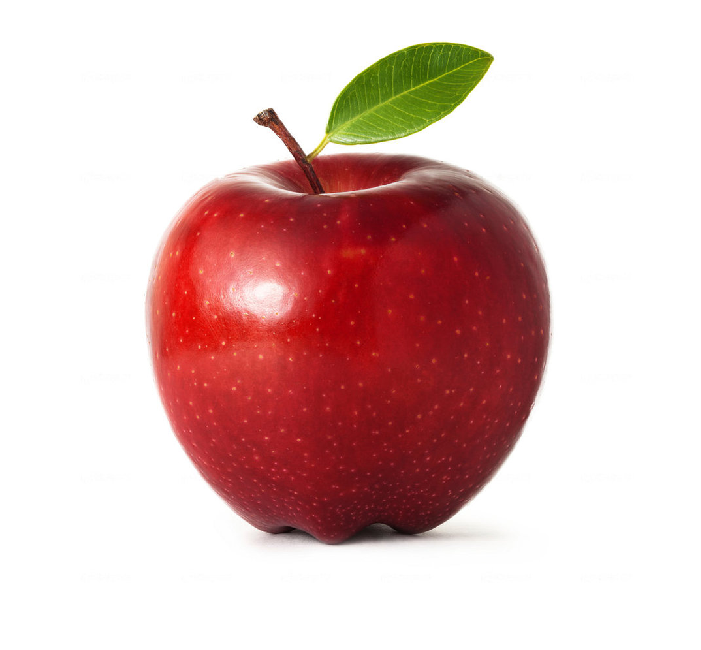

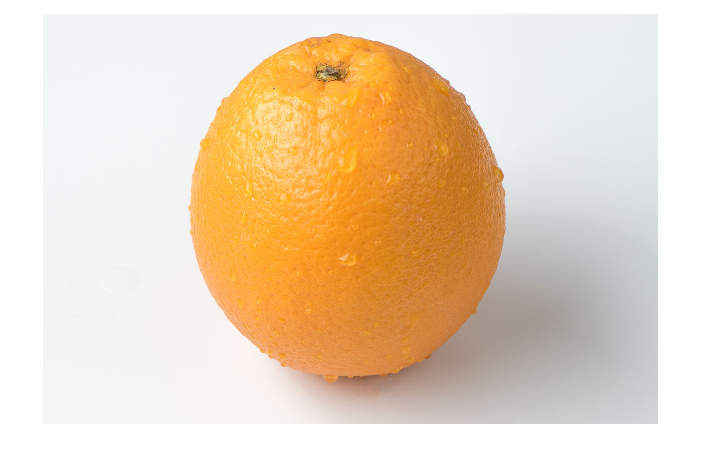

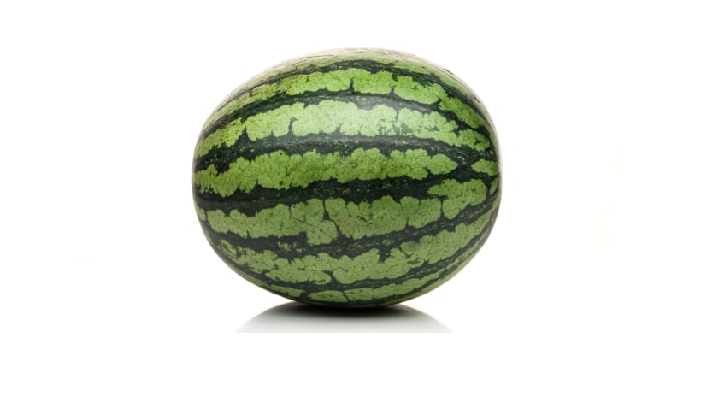

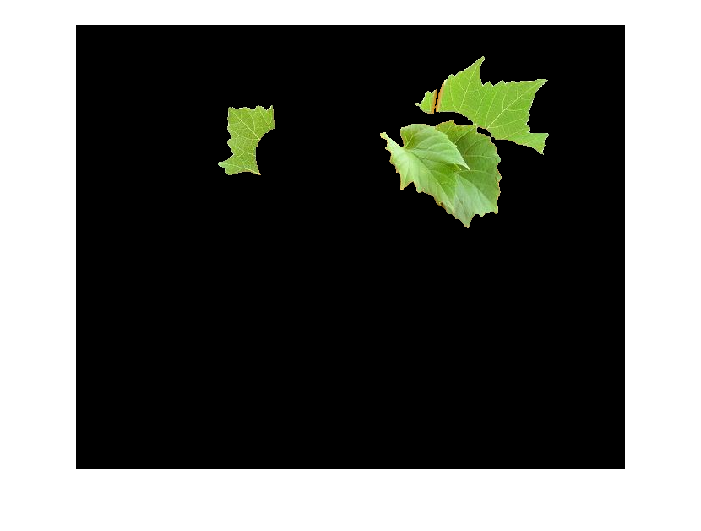

image_folder = 'buah';
filenames = dir(fullfile(image_folder, '*.jpg'));
total_images = numel(filenames);
ciri_database = zeros(total_images,6);
 
for n = 1:total_images
    full_name = fullfile(image_folder, filenames(n).name);
    I = imread(full_name);
    % Color-Based Segmentation Using K-Means Clustering
    cform = makecform('srgb2lab');
    lab = applycform(I,cform);

    ab = double(lab(:,:,2:3));
    nrows = size(ab,1);
    ncols = size(ab,2);
    ab = reshape(ab,nrows*ncols,2);
 
    nColors = 3;
    [cluster_idx, cluster_center] = kmeans(ab,nColors,'distance','sqEuclidean', ...
                                      'Replicates',3);
 
    pixel_labels = reshape(cluster_idx,nrows,ncols);
    RGB = label2rgb(pixel_labels);

    rgb_label = repmat(pixel_labels,[1 1 3]);
 
    color = I;
    color(rgb_label ~= 1) = 0;
    segmented_images = color;

    % segmentation
    area_cluster1 = sum(sum(pixel_labels==1));
    area_cluster2 = sum(sum(pixel_labels==2));
    area_cluster3 = sum(sum(pixel_labels==3));
     
    [~,cluster_apel] = min(area_cluster1);
    apel_bw = (pixel_labels==cluster_apel);
    apel_bw = imfill(apel_bw,'holes');
    apel_bw = bwareaopen(apel_bw,1000);
     
    apel = I;
    R = apel(:,:,1);
    G = apel(:,:,2);
    B = apel(:,:,3);
    R(~apel_bw) = 0;
    G(~apel_bw) = 0;
    B(~apel_bw) = 0;
    apel_rgb = cat(3,R,G,B);
    
    % RGB Features Extraction
    R_stats = regionprops(apel_bw,R,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
    G_stats = regionprops(apel_bw,G,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
    B_stats = regionprops(apel_bw,B,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
     
    R_pix_val = R_stats.PixelValues;
    G_pix_val = G_stats.PixelValues;
    B_pix_val = B_stats.PixelValues;

    R_mean = R_stats.MeanIntensity;
    G_mean = G_stats.MeanIntensity;
    B_mean = B_stats.MeanIntensity;
     
    R_max = R_stats.MaxIntensity;
    G_max = G_stats.MaxIntensity;
    B_max = B_stats.MaxIntensity;
     
    R_min = R_stats.MinIntensity;
    G_min = G_stats.MinIntensity;
    B_min = B_stats.MinIntensity;
     
    % HSV features extraction
    apel = rgb2hsv(I);
    H = apel(:,:,1);
    S = apel(:,:,2);
    V = apel(:,:,3);
    H(~apel_bw) = 0;
    S(~apel_bw) = 0;
    V(~apel_bw) = 0;
    apel_hsv = cat(3,H,S,V);
     
    H_stats = regionprops(apel_bw,H,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
    S_stats = regionprops(apel_bw,S,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
    V_stats = regionprops(apel_bw,V,'PixelValues','MeanIntensity',...
        'MaxIntensity','MinIntensity');
     
    H_mean = H_stats.MeanIntensity;
    S_mean = S_stats.MeanIntensity;
    V_mean = V_stats.MeanIntensity;
     
    H_max = H_stats.MaxIntensity;
    S_max = S_stats.MaxIntensity;
    V_max = V_stats.MaxIntensity;
     
    H_min = H_stats.MinIntensity;
    S_min = S_stats.MinIntensity;
    V_min = V_stats.MinIntensity;
     
    % Shape features extraction
    reg_stats = regionprops(apel_bw,'Area','Perimeter','Eccentricity');
     
    area = reg_stats.Area;
    perimeter = reg_stats.Perimeter;
    eccentricity = reg_stats.Eccentricity;

    %check the picture
    figure, imshow(apel_rgb);

ciri_database(n,:) = [n,area,perimeter,eccentricity,V_mean,V_min];
end


save ciri_database ciri_database

load("ciri_database.mat","ciri_database");
load('data.mat','ciri_data')
 
[num,~] = size(ciri_database);
 
dist = zeros(1,num);
for n = 1:num
    data_base = ciri_database(n,:);
    jarak = sum((data_base-ciri_data).^2).^0.5;
    dist(n) = jarak;
    %test kecocokan
    fprintf('%d \n',jarak)
end

3.468095e-01 
0 
9.375120e-01 
7.366030e-01 
8.355888e-01 
3.503632e-01 


 
[~,id] = min(dist);
 
if isempty(id)
    set(handles.edit1,'String','Unknown')
else
    switch id
        case 1
            tingkat = 'Apel';
        case 2
            tingkat = 'Jeruk';
        case 3
            tingkat = 'Semangka';
        case 4
            tingkat = 'Anggur';
        case 5
            tingkat = 'Pisang';
        case 6
            tingkat = 'Stroberi';
    end
    save('hasil.mat',"tingkat");
end